% Live Script sull'efficienza di un diffusore supersonico con rampa esterna:
% il codice rallenta subsonicamente il flusso prima con un urto obliquo,
% poi con uno normale. Il Mach è scelto dall'utente

clear
clc


M = 1.8;
p1 = 10e5;
T1 = 300;
gamma = 1.4;
theta_max = theta_max(M,gamma) - 0.01;        % si limita l'angolo a quelli che producono urti attaccati
theta = linspace(0.01,theta_max,100);


[pi_inlet] = Inlet_urto(theta,p1,T1,M,gamma);


perdita di pressione nel diffusore percentuale, funzione dell'angolo di rampa

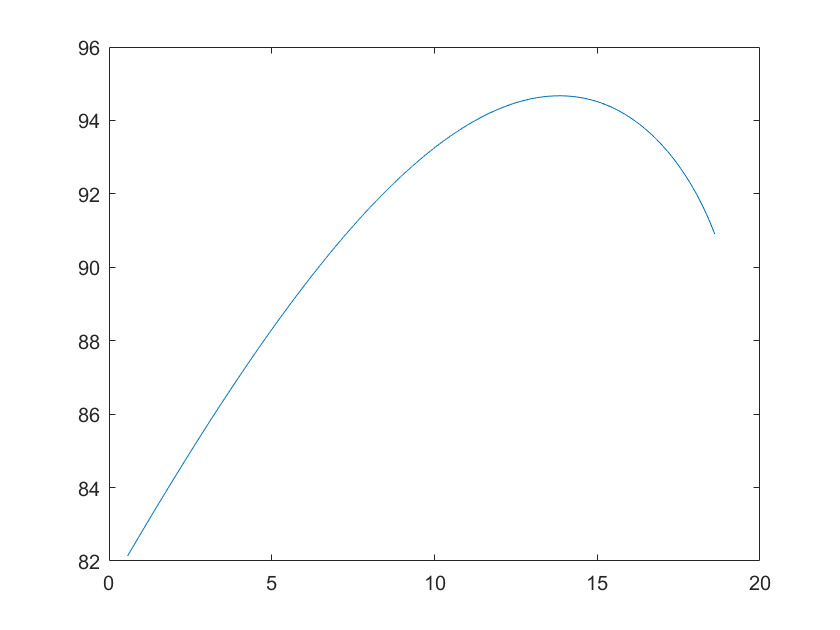

plot(theta.*180./pi,pi_inlet*100)    % asse x angolo di rampa; asse y efficienza % del diffusore

% Parte 2:
% Visto che esiste un massimo di efficienza per un determinato numero di
% Mach, si calcola quale sia il miglior angolo in funzione di M e quale
% perdita di pressione totale produce

clear
clc



M = linspace(1.5,5,100);            % asse numero di Mach
p1 = 1e5;
T1 = 280;
gamma = 1.4;
theta_opt = [];
eff_vec= [];

for i = [1:length(M)]
   
    theta = linspace(0.001,theta_max(M(i),gamma)-0.01,500);
    [pi_inlet] = Inlet_urto(theta,p1,T1,M(i),gamma);
    [eff,j] = max(pi_inlet);
    theta_opt(i) = theta(j);
    eff_vec(i) = eff * 100;
    
end


Valore ottimale dell'angolo di rampa in funzione del mach di volo

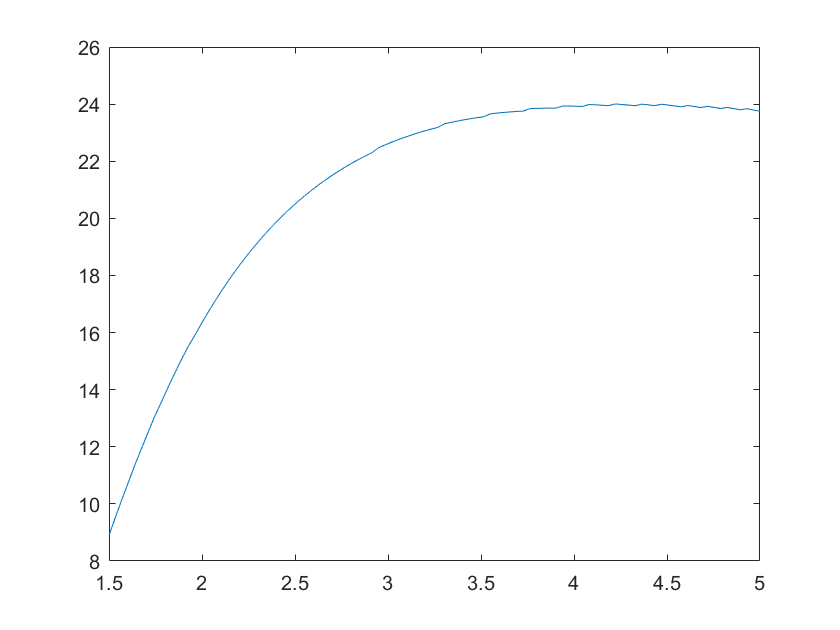

plot(M,theta_opt *180/pi);    % asse x numero di Mach; asse y angolo ottimale di rampa

Minima perdita di pressione totale (percentuale) in funzione del numero di Mach

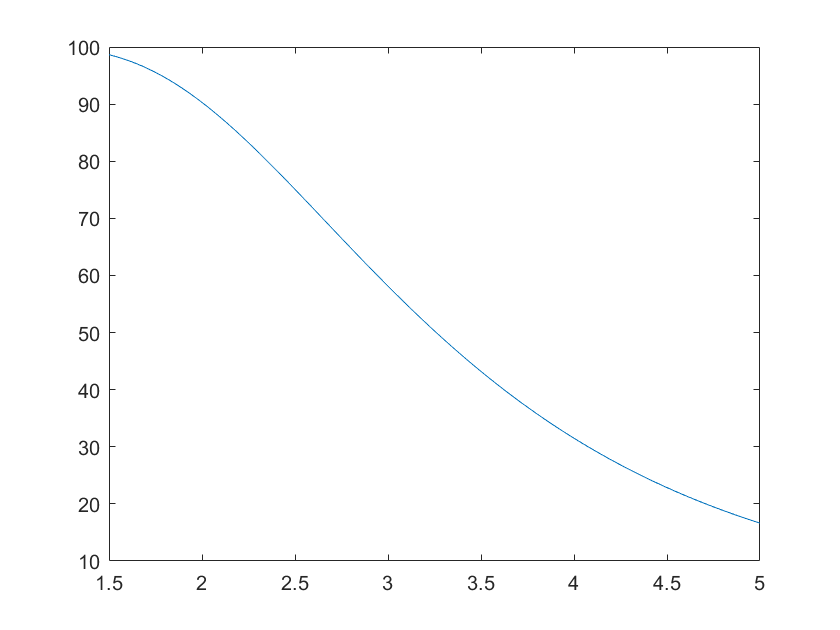

plot(M,eff_vec)   % asse x numero di Mach; asse y  massima efficienza % del diffusore 